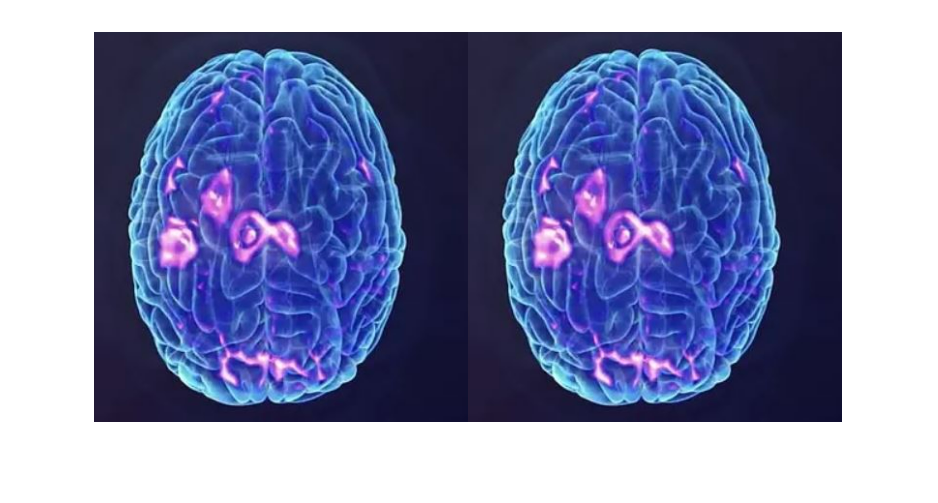

Pd1=imread("C:\Users\nipun\OneDrive\Desktop\College\Research\PCA\depressedbrain\MicrosoftTeams-image (1).png");
Pd2=imread("C:\Users\nipun\OneDrive\Desktop\College\Research\PCA\depressedbrain\MicrosoftTeams-image.png");
Pn1=imread("C:\Users\nipun\OneDrive\Desktop\College\Research\PCA\normalbrain\MicrosoftTeams-image (4).png");
Pn2=imread("C:\Users\nipun\OneDrive\Desktop\College\Research\PCA\normalbrain\MicrosoftTeams-image (3).png");
% Regularization of Matrix
Pd2 = imresize(Pd1,1);
Pn2 = imresize(Pn1,1);
Depressed=[Pd1 Pd2];
Normal=[Pn1 Pn2];
imshow(Depressed);

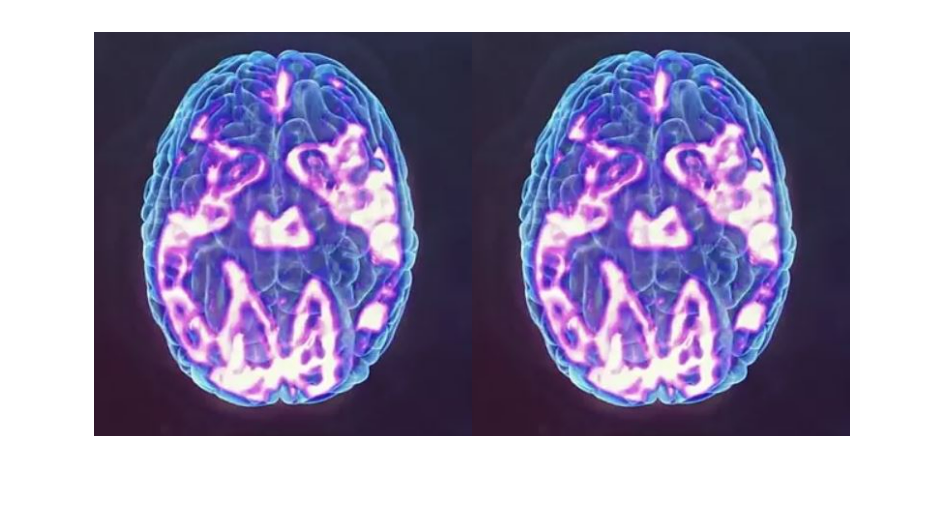

imshow(Normal);

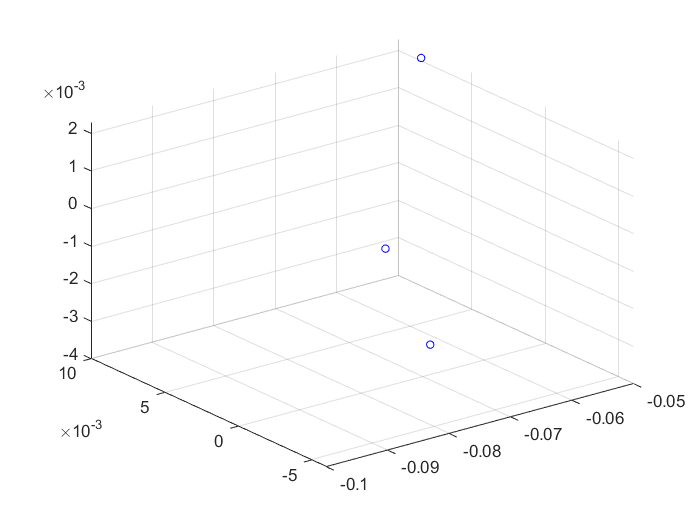

D=double(Depressed);
N=double(Normal);
desired = [];
for n = 1:size(Depressed,3)
  desired = cat(1,Depressed(:,n,:),desired);
end
RDepressed = reshape(Depressed,[],size(Depressed,3));
RDepressed=im2double(RDepressed);
% Calculation of Covariance Matrix and performing SVD
CovarianceMatrixDepressed=cov(RDepressed,1);
[Ud,Zd,Vd]=svd(CovarianceMatrixDepressed);
% PCA Process
PC1Depressed=zeros(size(CovarianceMatrixDepressed,1),1);
PC2Depressed=zeros(size(CovarianceMatrixDepressed,1),1);
PC3Depressed=zeros(size(CovarianceMatrixDepressed,1),1);
figure 
for i=1:size(CovarianceMatrixDepressed,1)
    x=Vd(:,1)'*CovarianceMatrixDepressed(i,:)';
    y=Vd(:,2)'*CovarianceMatrixDepressed(i,:)';
    z=Vd(:,3)'*CovarianceMatrixDepressed(i,:)';
    PC1Depressed(i)=x;
    PC2Depressed(i)=y;
    PC3Depressed(i)=z;
    scatter3(x,y,z,20,'blue');
    %scatter(x,y,20,"black")
    hold on
end

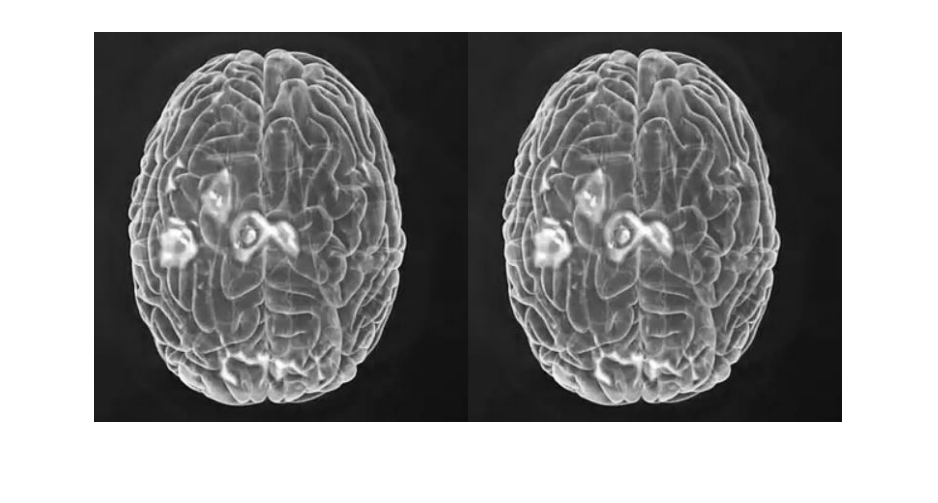

% cast(PC1Depressed,'uint8');
% cast(PC2Depressed,'uint8');
% cast(PC3Depressed,'uint8');
% imshow(PC1Depressed);
% imshow(PC2Depressed);
% imshow(PC3Depressed);

X = reshape(D,size(D,1)*size(D,2),3);
coeff = pca(X);
Itransformed = X*coeff;
Ipc1 = reshape(Itransformed(:,1),size(D,1),size(D,2));
Ipc2 = reshape(Itransformed(:,2),size(D,1),size(D,2));
Ipc3 = reshape(Itransformed(:,3),size(D,1),size(D,2));
figure, imshow(Ipc1,[]);

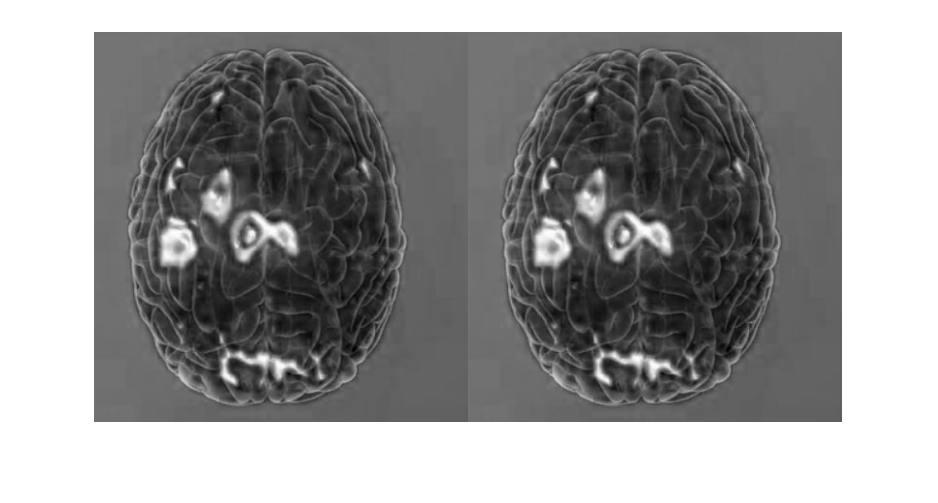

figure, imshow(Ipc2,[]);

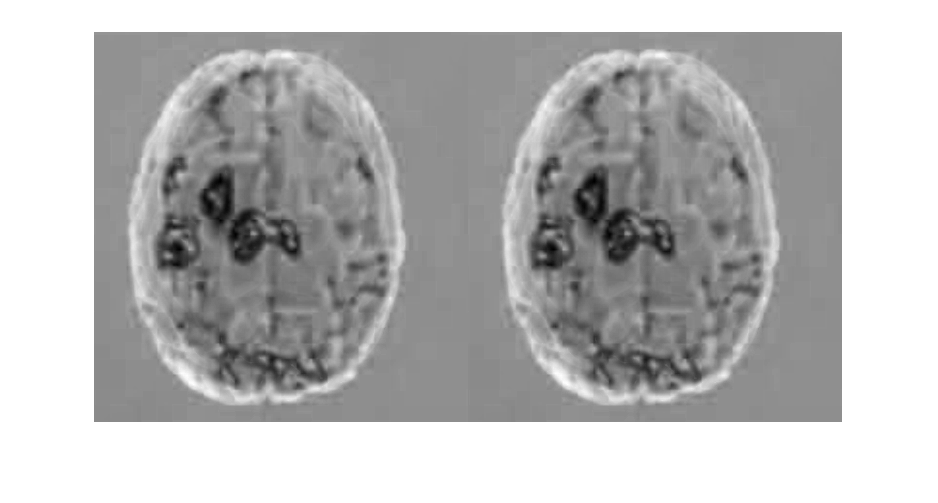

figure, imshow(Ipc3,[]);

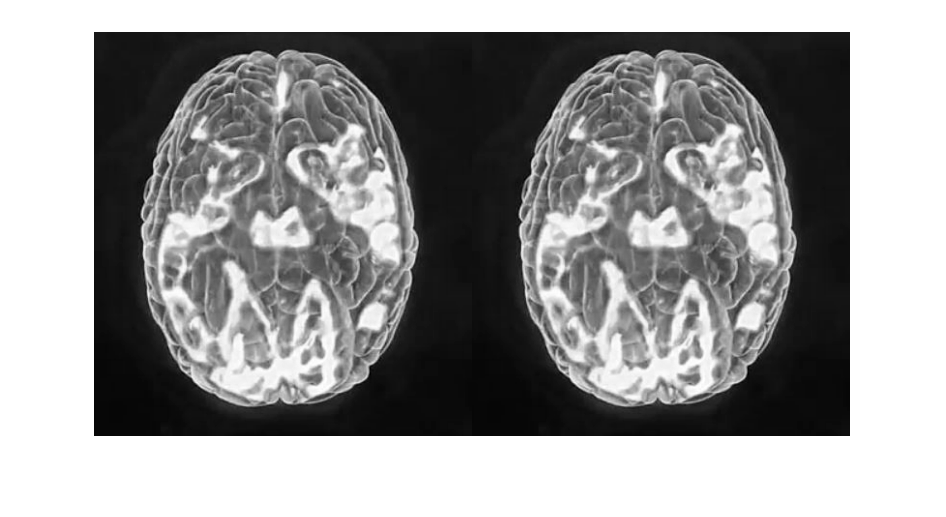


X1 = reshape(N,size(N,1)*size(N,2),3);
coeff = pca(X);
Itransformed = X1*coeff;
Ipc1 = reshape(Itransformed(:,1),size(N,1),size(N,2));
Ipc2 = reshape(Itransformed(:,2),size(N,1),size(N,2));
Ipc3 = reshape(Itransformed(:,3),size(N,1),size(N,2));
figure, imshow(Ipc1,[]);

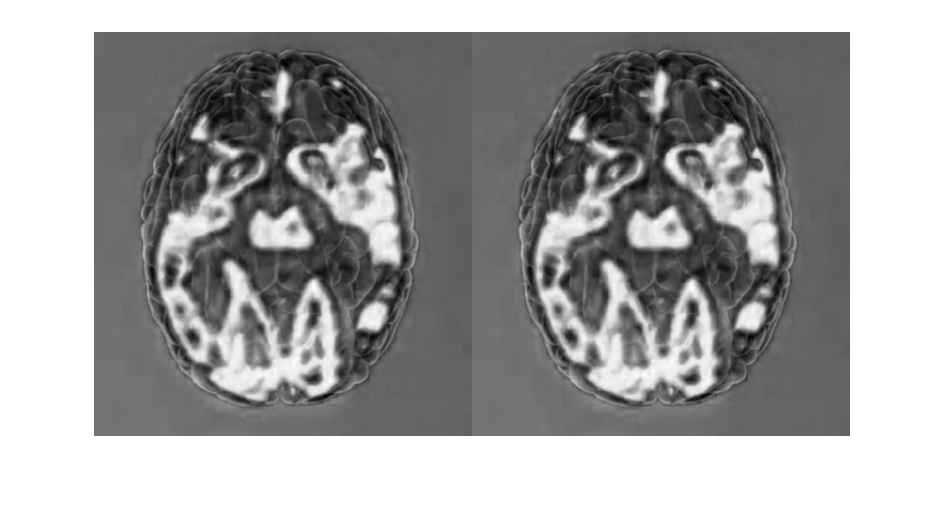

figure, imshow(Ipc2,[]);

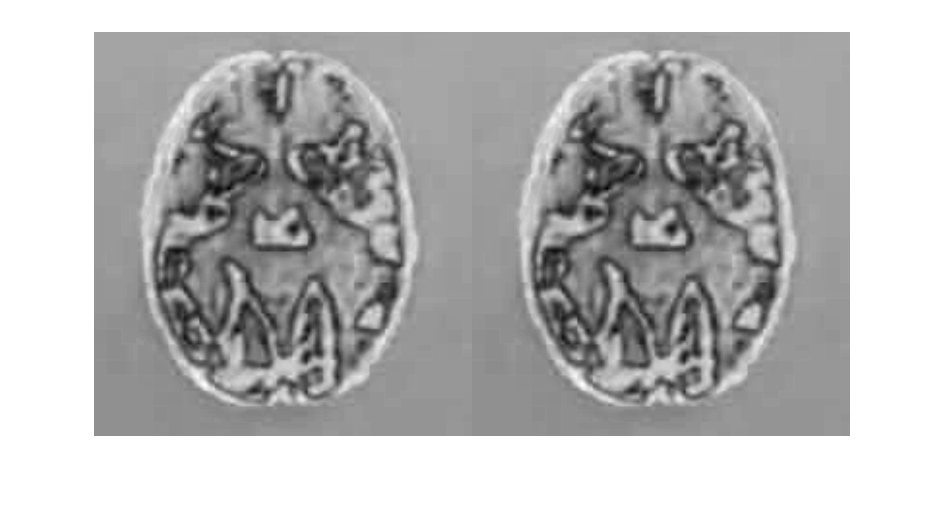

figure, imshow(Ipc3,[]);